clear all;
clc;
close all;


To = 1                       

To = 1

fo = 1/To

fo = 1

wo = 2*pi*fo

wo = 6.2832

## 1 Sinal periodico

gt = @(t) (exp(-t)) %%% G(t)

gt = function_handle with value:
    @(t)(exp(-t))


## 2 Base de fourier

gnt = @(t) (exp(-j*n*wo*t)) %%% Gn(t)

gnt = function_handle with value:
    @(t)(exp(-j*n*wo*t))


## 3 Primeira projeção

syms n t
c1 = (1/To)*int(gt*exp(-j*n*wo*t),t,0,To) %%% Monta a integral

$$c1 = -\frac{{\mathrm{e}}^{-1}\,{\mathrm{e}}^{-2\,\pi \,n\,\mathrm{i}}-1}{1+2\,\pi \,n\,\mathrm{i}}$$


n = [-1:1:1]

n =     -1     0     1



A = eval(c1) %%% Calcula a equação, mas agora tendo os valores de "n"

A =    0.0156 + 0.0981i   0.6321 + 0.0000i   0.0156 - 0.0981i


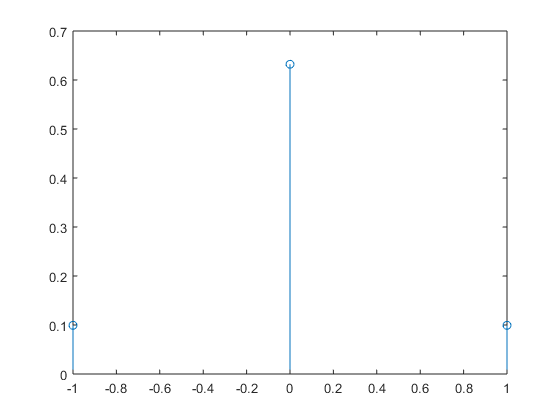

tempo = [0:0.01:1];

figure()            %%% Gera uma imagem
stem(n*fo,abs(A))   %%% Plota uma sequencia discreta


C_1 = A(1,1)        %%% Olha para a matriz gerada como reposta e pega a posição (1,1)

C_1 = 0.0156 + 0.0981i

C0 = A(1,2)

C0 = 0.6321

C1 = A(1,3)

C1 = 0.0156 - 0.0981i



P1 = C1*(exp(-j*wo*tempo))+C_1*(exp(j*wo*tempo)) %%% Calcula P1 com valores

P1 =     0.0312    0.0188    0.0064   -0.0061   -0.0186   -0.0309   -0.0432   -0.0553   -0.0672   -0.0788   -0.0901   -0.1010   -0.1116   -0.1217   -0.1313   -0.1404   -0.1490   -0.1569   -0.1643   -0.1710   -0.1770   -0.1823   -0.1869   -0.1908   -0.1939   -0.1962   -0.1978   -0.1986   -0.1986   -0.1978   -0.1963   -0.1940   -0.1909   -0.1870   -0.1824   -0.1771   -0.1711   -0.1644   -0.1571   -0.1492   -0.1406   -0.1315   -0.1219   -0.1118   -0.1013   -0.0903   -0.0791   -0.0675   -0.0556   -0.0435


P1T = @(t) C1*(exp(-j*wo*t))+C_1*(exp(j*wo*t))   %%% Gera uma expressão de P1 em função de "t"

P1T = function_handle with value:
    @(t)C1*(exp(-j*wo*t))+C_1*(exp(j*wo*t))


r1 = gt(tempo)-P1   %%% Calcula R1 com valores

r1 =     0.9688    0.9712    0.9738    0.9765    0.9793    0.9822    0.9850    0.9877    0.9903    0.9927    0.9949    0.9969    0.9985    0.9998    1.0007    1.0011    1.0011    1.0006    0.9995    0.9979    0.9957    0.9929    0.9894    0.9853    0.9805    0.9750    0.9689    0.9620    0.9544    0.9461    0.9371    0.9274    0.9170    0.9059    0.8942    0.8818    0.8688    0.8552    0.8410    0.8262    0.8109    0.7952    0.7790    0.7623    0.7453    0.7280    0.7103    0.6925    0.6744    0.6561


r1t = @(t) (gt(t)-P1T(t)) %%% Gera uma expressão de R1 em função de "t"

r1t = function_handle with value:
    @(t)(gt(t)-P1T(t))


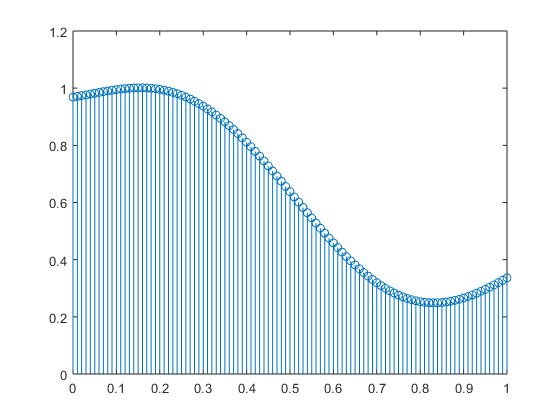


figure()
stem(tempo,abs(r1))

## 4.1 Segunda projeção

syms n t
c2 = (1/To)*int(gt*exp(-j*n*wo*t),t,0,To)

$$c2 = -\frac{{\mathrm{e}}^{-1}\,{\mathrm{e}}^{-2\,\pi \,n\,\mathrm{i}}-1}{1+2\,\pi \,n\,\mathrm{i}}$$


n = [-2:1:2]

n =     -2    -1     0     1     2



B = eval(c2)

B =    0.0040 + 0.0500i   0.0156 + 0.0981i   0.6321 + 0.0000i   0.0156 - 0.0981i   0.0040 - 0.0500i


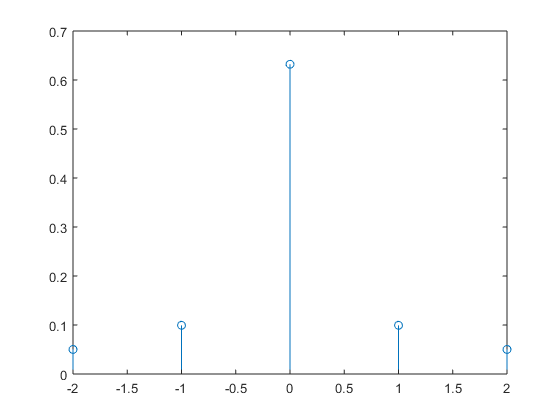

tempo = [0:0.01:1];

figure()
stem(n*fo,abs(B))



C_2 = B(1,1)

C_2 = 0.0040 + 0.0500i

C_1 = B(1,2)

C_1 = 0.0156 + 0.0981i

C0 = B(1,3)

C0 = 0.6321

C1 = B(1,4)

C1 = 0.0156 - 0.0981i

C2 = B(1,5)

C2 = 0.0040 - 0.0500i



P2 = C2*(exp(-2*j*wo*tempo))+C_2*(exp(2*j*wo*tempo))

P2 =     0.0080   -0.0046   -0.0172   -0.0294   -0.0412   -0.0523   -0.0626   -0.0720   -0.0801   -0.0871   -0.0926   -0.0967   -0.0993   -0.1003   -0.0997   -0.0975   -0.0938   -0.0887   -0.0821   -0.0742   -0.0652   -0.0551   -0.0442   -0.0326   -0.0204   -0.0080    0.0046    0.0172    0.0294    0.0412    0.0523    0.0626    0.0720    0.0801    0.0871    0.0926    0.0967    0.0993    0.1003    0.0997    0.0975    0.0938    0.0887    0.0821    0.0742    0.0652    0.0551    0.0442    0.0326    0.0204


r2 = gt(tempo)-(P1 + P2)

r2 =     0.9608    0.9758    0.9910    1.0059    1.0205    1.0345    1.0476    1.0596    1.0704    1.0798    1.0875    1.0936    1.0978    1.1000    1.1003    1.0986    1.0949    1.0893    1.0816    1.0722    1.0609    1.0480    1.0336    1.0179    1.0009    0.9830    0.9642    0.9448    0.9250    0.9049    0.8848    0.8648    0.8451    0.8258    0.8071    0.7892    0.7721    0.7559    0.7407    0.7265    0.7134    0.7013    0.6903    0.6802    0.6711    0.6628    0.6552    0.6483    0.6418    0.6357


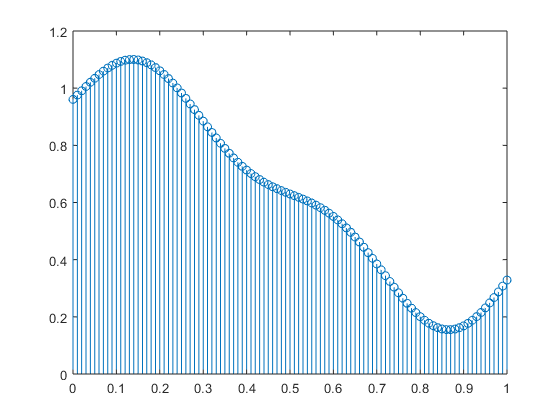


figure()
stem(tempo,abs(r2))

## 4.2 coeficientes da segunda projeção utilizando o residuo 1

syms n t
c2_novo = (1/To)*int(r1t*exp(-j*n*wo*t),t,0,To)

$$c2\_novo = -\frac{{\mathrm{e}}^{-1}\,{\mathrm{e}}^{-2\,\pi \,n\,\mathrm{i}}-1}{1+2\,\pi \,n\,\mathrm{i}}+\frac{\left({\mathrm{e}}^{-2\,\pi \,n\,\mathrm{i}}-1\right)\,\left(\frac{441891890617475}{9007199254740992}-\frac{2250536918527815}{288230376151711744}\,\mathrm{i}\right)}{\pi \,\left(n-1\right)}+\frac{\left({\mathrm{e}}^{-2\,\pi \,n\,\mathrm{i}}-1\right)\,\left(-\frac{441891890617475}{9007199254740992}-\frac{2250536918527815}{288230376151711744}\,\mathrm{i}\right)}{\pi \,\left(n+1\right)}$$

%%% Cria uma integral que dessa vez
%%% utiliza o R1 para comparação

n = [-2:1:2]

n =     -2    -1     0     1     2



D = eval(c2_novo)

D =    0.0040 + 0.0500i     -Inf +    Infi   0.6321 + 0.0000i      Inf +    Infi   0.0040 - 0.0500i


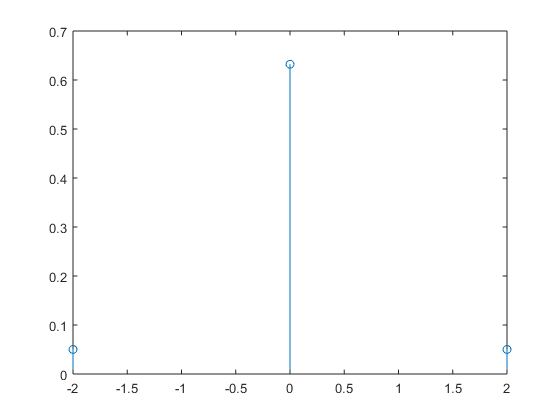

tempo = [0:0.01:1];

figure()
stem(n*fo,abs(D))



C_2novo = D(1,1)

C_2novo = 0.0040 + 0.0500i


C2novo = D(1,5)

C2novo = 0.0040 - 0.0500i

## 5 Estrutura recorrente para determinar a projeção

syms n t
cn = (1/To)*int(gt*exp(-j*n*wo*t),t,0,To)

$$cn = -\frac{{\mathrm{e}}^{-1}\,{\mathrm{e}}^{-2\,\pi \,n\,\mathrm{i}}-1}{1+2\,\pi \,n\,\mathrm{i}}$$


N = 2

N = 2

%%%N = input("Quantas harmonicas:") %%% estrutura para ser interativo
n = [-N:1:N]

n =     -2    -1     0     1     2



tempo = [0:1/(N*10):1]; 
%%% Fala q o tempo vai de 0 a 1, porém agora o passo varia com o numero de harmonicas

E = eval(cn)

E =    0.0040 + 0.0500i   0.0156 + 0.0981i   0.6321 + 0.0000i   0.0156 - 0.0981i   0.0040 - 0.0500i


figure()
stem(n*fo,abs(E))


ult = length(E) %%% descobre o comprimento de "E" e guarda em ult

ult = 5

CoN = E(1,ult)  %%% Utiliza de ult para pegar a ultima casa de "E"

CoN = 0.0040 - 0.0500i

Co_N = E(1,1)

Co_N = 0.0040 + 0.0500i


PN = CoN*(exp(-N*j*wo*tempo))+Co_N*(exp(N*j*wo*tempo))

PN =     0.0080   -0.0523   -0.0926   -0.0975   -0.0652   -0.0080    0.0523    0.0926    0.0975    0.0652    0.0080   -0.0523   -0.0926   -0.0975   -0.0652   -0.0080    0.0523    0.0926    0.0975    0.0652    0.0080





PNT = @(t) CoN*(exp(-N*j*wo*t))+Co_N*(exp(N*j*wo*t))

PNT = function_handle with value:
    @(t)CoN*(exp(-N*j*wo*t))+Co_N*(exp(N*j*wo*t))


Ptotal = 0 %%% Inicia Ptotal

Ptotal = 0

for K = 1:N %%% faz com que K varie de 0 até N e rode N vezes
    n = K;
    %%%CKN = E(1,(ult-K));
    CNa = eval(cn);
    %%%CK_N = E(1,(K+1));
    n = -K;
    CNb = eval(cn);
    
    P = @(t) CNa*(exp(-K*j*wo*t))+CNb*(exp(K*j*wo*t));
    Ptotal = Ptotal + P(tempo); %%% Soma a cada vez um P, começando em P0 até Pn
end

RN = gt(tempo)-(Ptotal)

RN =     0.9608    1.0345    1.0875    1.0986    1.0609    0.9830    0.8848    0.7892    0.7134    0.6628    0.6298    0.5983    0.5514    0.4792    0.3848    0.2841    0.2007    0.1577    0.1684    0.2312    0.3287


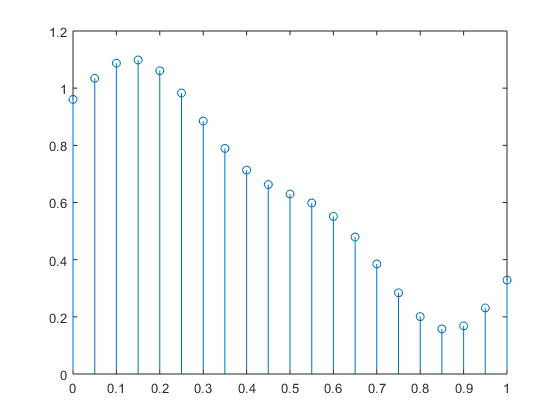


figure()
stem(tempo,abs(RN))